K = 2; % number of clusters (number of Gaussians)
D = 2; % number of dimensions in each Gaussian

mu1 = [3, 4];
mu2 = [9, 8];

sigma1 = [1, 0.5; 0.5, 1];
sigma2 = [1, -0.2; -0.2, 1];

phi = [0.3, 0.7];
N = 1000;

## Step 1: generate sample from the mixture of two bivariate Gaussians

rng('default') % reproducible

X = sampleGaussianMixture(N, {mu1, mu2}, {sigma1, sigma2}, phi);

## Step 2: implement the EM algorithm and get some results

[MU, SIGMA, PI] = EMAlgo(X, phi, K);

Num iterations in EM algo: 2 


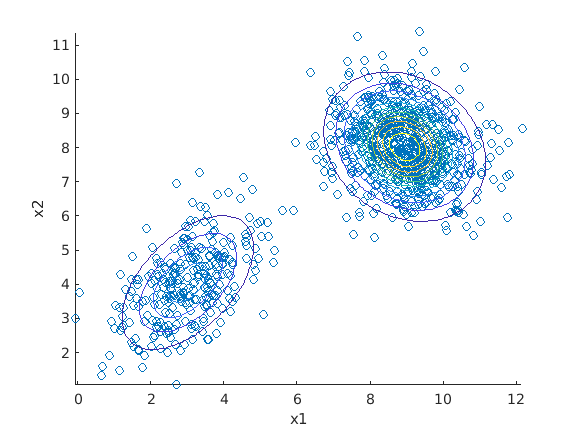


% Plotting the resulting mixture of gaussians: 

% Probability density of mixture using the given parameters: 
p_initial = @(x) phi(1) * mvnpdf(x, mu1, sigma1) + phi(2) * mvnpdf(x, mu2, sigma2) ;

% PDF of mixture using the parameters estimated by the EM algorithm.  
p_new = @(x) PI(1) * mvnpdf(x, MU(1,:), SIGMA{1}) + PI(2) * mvnpdf(x, MU(2,:), SIGMA{2}) ;


% Plotting the sampled data
figure(1); clf; 
X1 = X(:, 1);
X2 = X(:, 2);
scatter(X1, X2) % the two dimensions sampled from data

hold on; 

% Deterministic part: using contour to plot the mixture of gaussians
% making the grid of values
x1 = linspace(min(X1), max(X1));     % 1 x 100
x2 = linspace(min(X2), max(X2));     % 1 x 100

% joining xx2 on the right of xx1
[xx1 xx2] = meshgrid(x1, x2);        % xx1 is 100 x 100

% get the values from the multivariate pdf using the meshgrid
f = p_new([xx1(:), xx2(:)]);

% contour plot 
% note: must reshape f to be 100x100 since both the  xx1 and xx2 are 100 x 100. 
contour(xx1, xx2, reshape(f, 100, 100))
xlabel('x1') % dimension 1
ylabel('x2') % dimension 2

% Showing the results in a table
% Means comparison
meanTable = table(mu1', MU(1,:)', mu2', MU(2,:)', 'VariableNames', {'GivenMu1', 'EstMu1', 'GivenMu2', 'EstMu2'})

meanTable = 2×4 table
    GivenMu1         EstMu1         GivenMu2         EstMu2     
    ________    ________________    ________    ________________

    3           3.01497012150705    9           8.94951378554843
    4           4.04807921348502    8           8.02446374233351




% Sigma comparison
sigma1Table = table(sigma1, SIGMA{1}, 'VariableNames', {'GivenSigma1', 'EstSigma1'})

sigma1Table = 2×2 table
    GivenSigma1                  EstSigma1               
    ___________    ______________________________________

      1    0.5       1.0631315291412    0.616813729204621
    0.5      1     0.616813729204621     1.26494570117119



sigma2Table = table(sigma2, SIGMA{2}, 'VariableNames', {'GivenSigma2', 'EstSigma2'})

sigma2Table = 2×2 table
    GivenSigma2                   EstSigma2               
    ____________    ______________________________________

       1    -0.2    0.989165413178025    -0.19991777511479
    -0.2       1    -0.19991777511479     0.96196353281825



 % Prior mixture probabilities comparison
phiTable= table(phi', PI', 'VariableNames', {'GivenPrior', 'EstPrior'})

phiTable = 2×2 table
    GivenPrior        EstPrior     
    __________    _________________

    0.3            0.28104507414632
    0.7           0.718954925853679


## Doing the EM algorithm steps from the start for B = 100 iterations

B = 100;
[avgMU, avgSIGMA, avgPI] = averageEMResults(B, {mu1, mu2}, {sigma1, sigma2}, N, phi);

Num iterations in EM algo: 2 
Num iterations in EM algo: 2 
Num iterations in EM algo: 1 
Num iterations in EM algo: 1 
Num iterations in EM algo: 1 
Num iterations in EM algo: 2 
Num iterations in EM algo: 3 
Num iterations in EM algo: 3 
Num iterations in EM algo: 2 
Num iterations in EM algo: 3 
Num iterations in EM algo: 2 
Num iterations in EM algo: 1 
Num iterations in EM algo: 3 
Num iterations in EM algo: 2 
Num iterations in EM algo: 3 
Num iterations in EM algo: 3 
Num iterations in EM algo: 2 
Num iterations in EM algo: 3 
Num iterations in EM algo: 3 
Num iterations in EM algo: 3 
Num iterations in EM algo: 2 
Num iterations in EM algo: 2 
Num iterations in EM algo: 2 
Num iterations in EM algo: 1 
Num iterations in EM algo: 1 
Num iterations in EM algo: 1 
Num iterations in EM algo: 1 
Num iterations in EM algo: 1 
Num iterations in EM algo: 1 
Num iterations in EM algo: 1 
Num iterations in EM algo: 1 
Num iterations in EM algo: 1 
Num iterations in EM algo: 3 
Num iterat


% Compare original vs estimated parameters in a table

% Means comparison
table(mu1', avgMU(1,:)', mu2', avgMU(2,:)', 'VariableNames', {'GivenMu1', 'EstMu1', 'GivenMu2', 'EstMu2'})

ans = 2×4 table
    GivenMu1         EstMu1         GivenMu2        EstMu2     
    ________    ________________    ________    _______________

    3           6.60264787024625    9           5.3958211499299
    4           6.40309058748796    8           5.6024047116782




% Sigma comparison
table(sigma1, avgSIGMA{1}, 'VariableNames', {'GivenSigma1', 'EstSigma1'})

ans = 2×2 table
    GivenSigma1                   EstSigma1                
    ___________    ________________________________________

      1    0.5      0.997236501620181    0.0732853396840627
    0.5      1     0.0732853396840627     0.998108865814018



table(sigma2, avgSIGMA{2}, 'VariableNames', {'GivenSigma2', 'EstSigma2'})

ans = 2×2 table
    GivenSigma2                   EstSigma2               
    ____________    ______________________________________

       1    -0.2    0.984961790229438    0.218806765812918
    -0.2       1    0.218806765812918    0.990363715056687



 % Prior mixture probabilities comparison
 table(phi', avgPI', 'VariableNames', {'GivenPrior', 'EstPrior'})

ans = 2×2 table
    GivenPrior        EstPrior     
    __________    _________________

    0.3           0.540908968780276
    0.7           0.459091031219724
